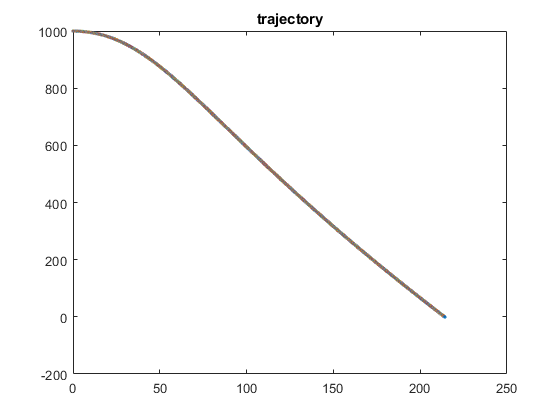

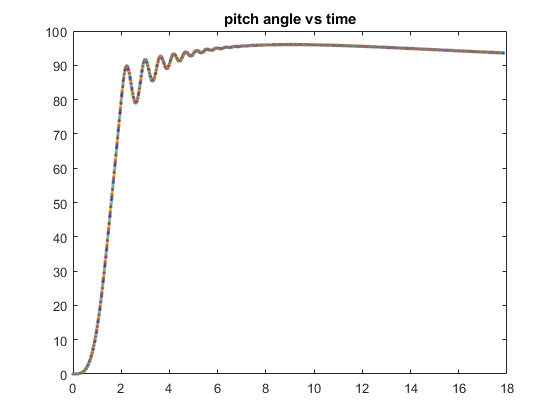

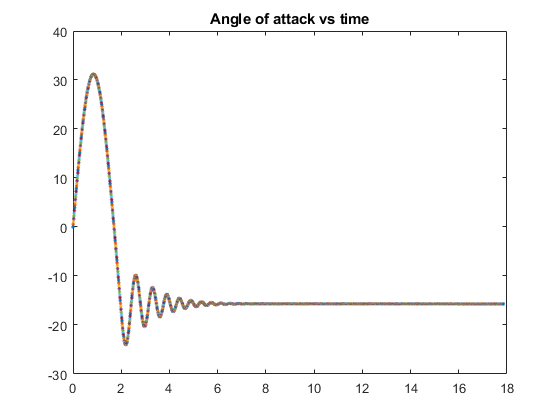

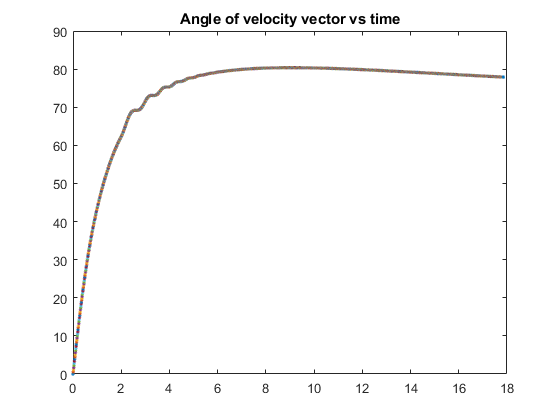

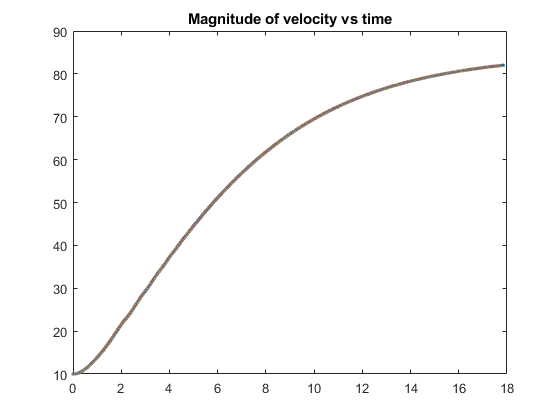

Lift_drag_moment_coefficients
Cdw=0;
Clw=0;
dw = 0;%distance between pressure centre due to wing from com

%Shape 2 (generates drags D2x and D2y) 

ds=0.05; %distance between pressure centre due to wing from com
Cd2=0.09; 
A=0.07; 

m = 5;          %mass of entire body.....'
Cdb=0.09;
Iz_no_wing= 0.1366 ; %no_wing
Iz_with_wing= 0.1366+0.02;
Iz=Iz_no_wing ;
g=9.81;
Vx=10; %Initial velocity
Vy=0 ; 
D1=0;
L1=0;
angular_rate= 0;
theta = 0;
wings_deployed = 0;
h=0.01;
rho=1.225;
t=0;
pi=3.14;
x=0;
y=0;
Aw=0.084;%Wing area
dw=0.06; %Distance bw com and cop along body
Ab=0.125*0.125*pi/4;
i=1;
ht_of_release=1000;%in meters
f1 = figure;
f2 = figure;
f3 = figure;
f4 = figure;
f5 = figure;

while (t<100)
    %phi
     % theta = angle made by fw aircraft with earth X
    if Vx==0
        alpha = 3.14/2;
    else
        alpha= atan(Vy/Vx); %angle made by velocity of wind/ Velocity of FW wind earth X
    end  
    %alpha,t
    Vnet = sqrt(Vx*Vx + Vy*Vy);
    phi = alpha - theta;
    %disp(phi*180/pi)
    
    Alpha_wing=180*phi/pi+5;
    Clw =0.08125*Alpha_wing + 0.8994;
    Cdw = 4.021e-06*Alpha_wing.^(4) + 6.66e-05*Alpha_wing.^(3) + 0.0006247*Alpha_wing.^(2) + 0.00708*Alpha_wing + 0.0427;
    Cdb= interp1(Alpha_droptank,Cd_droptank,180*phi/pi);
    Clb=interp1(Alpha_droptank,Cl_droptank,180*phi/pi);
    
    if wings_deployed
        %Forces in FW frame
        %disp("enters");
        %Cdw,Aw,Vnet
        D1= drag(Cdw,Aw,Vnet);      %Drag due to wing Ap
        L1= lift(Clw,Aw,Vnet);     %Lift due to wing Ap
        Iz=Iz_with_wing ;
    end
    L2= lift(Cdb,Ab,Vx);
    D2= drag(Cdb,Ab,Vy);
    
    %Forces in earth frame 
    Fx=(L1+L2)*sin(alpha)-(D1+D2)*cos(alpha);
    Fy= m*g -(L1+L2)*cos(alpha) - (D1+D2)*sin(alpha) ;
    
    

    %Moments 
    
    Mz = ( (L1+L2)*dw*cos(phi) + (D1+D2)*dw*sin(phi)); %note signs

    %Velocity rate or acceleration
    Vx_d = Fx/m;
    Vy_d = Fy/m;
    
    %Adding the velocity changes
    Vx_new = rk4(t, Vx_d, Vx,h);
    Vy_new = rk4(t, Vy_d, Vy, h);
    %plot(vx_new,t); hold on

    %Finding new positions 
    x_new = x + Vx_new*h;
    y_new = y + Vy_new*h;
    
    
    set(0, 'CurrentFigure', f1)
    plot(x, ht_of_release-y_new,'.'); hold on
    title("trajectory")
    %hold on
    %plot(t,Vnet,".");hold on

    angular_rate_d = Mz/Iz;
    %Adding the angular velocity changes
    angular_rate_new = rk4(t, angular_rate_d, angular_rate,h);
    
    angle_new = rk4(t, angular_rate_new, theta, h);
    set(0, 'CurrentFigure', f2)
    plot(t, theta*180/pi,'.'); hold on
    title("pitch angle vs time")

    set(0, 'CurrentFigure', f3)
    plot(t, phi*180/pi,'.'); hold on
    title("Angle of attack vs time")

    set(0, 'CurrentFigure', f4)
    plot(t, alpha*180/pi,'.'); hold on
    title("Angle of velocity vector vs time")
    
    set(0, 'CurrentFigure', f5)
    plot(t, Vnet,'.'); hold on
    title("Magnitude of velocity vs time")

    theta = angle_new;
    Vx = Vx_new;
    Vy = Vy_new;
    angular_rate = angular_rate_new;
    x=x_new;
    y=y_new;
    
    t= t + h;

    if t>2
        wings_deployed = 1;
    end

    if(y>=ht_of_release)
        break
    end

end

function f = drag(Cd,A,V)
    f = Cd*1.225*V*V*A*0.5;
end

function f = lift(Cl,A,V)
    f = Cl*1.225*V*V*A*0.5;
end

